path = 'E:\Data\Aurelie\data\chroms\119\220923\registration\';
path_biapy = strcat(path,'biapy_centroids_matched.csv');
path_gcamp = strcat(path,'centroid_gcamp_affine.csv');

% === Calcul de la distance 3D entre centroides biapy et gcamp ===

% Chargement des CSV (skip de la ligne 1 = header)
biapy  = readmatrix(path_biapy,   'NumHeaderLines', 1);
gcamp  = readmatrix(path_gcamp,        'NumHeaderLines', 1);

% Colonnes : 1=Z, 2=X, 3=Y
z_b = biapy(:,1);  x_b = biapy(:,2);  y_b = biapy(:,3);
z_g = gcamp(:,1);  x_g = gcamp(:,2);  y_g = gcamp(:,3);

% Distance euclidienne 3D pour chaque cellule
distances = sqrt((x_b - x_g).^2 + (y_b - y_g).^2 + (z_b - z_g).^2);

% Affichage
n = numel(distances);
fprintf('Nombre de cellules : %d\n', n);

Nombre de cellules : 304


fprintf('Distance moyenne   : %.4f\n', mean(distances));

Distance moyenne   : 6.0723


fprintf('Distance min       : %.4f\n', min(distances));

Distance min       : 0.4689


fprintf('Distance max       : %.4f\n', max(distances));

Distance max       : 25.0141



% Export CSV résultat
cell_idx = (1:n)';
T = table(cell_idx, z_b, x_b, y_b, z_g, x_g, y_g, distances, ...
    'VariableNames', {'cellule','Z_biapy','X_biapy','Y_biapy', ...
                      'Z_gcamp','X_gcamp','Y_gcamp','distance_3D'});
writetable(T, 'distances_biapy_gcamp.csv');
fprintf('Résultat exporté dans distances_biapy_gcamp.csv\n');

Résultat exporté dans distances_biapy_gcamp.csv


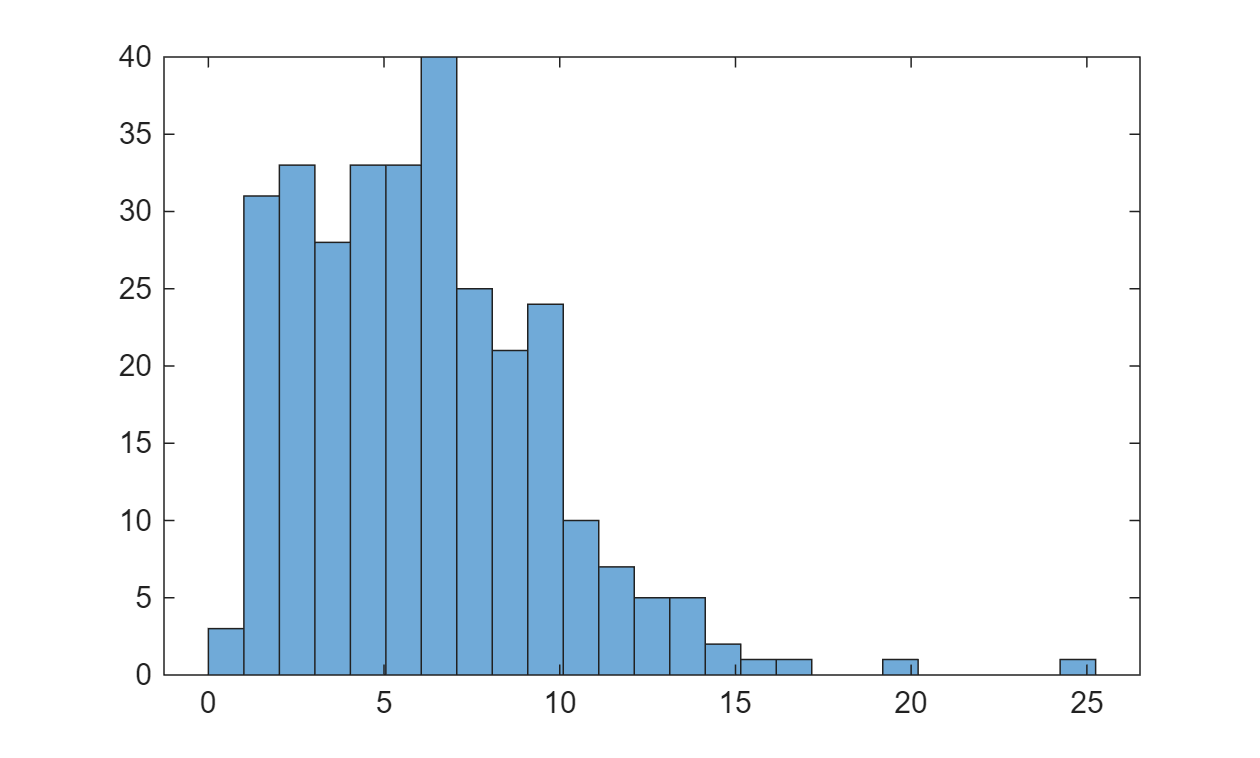


histogram(distances,25);


indices_sup = find(distances > 8);

fprintf('Nombre de cellules avec distance > 8 : %d\n', numel(indices_sup));

Nombre de cellules avec distance > 8 : 80


disp('Indices :');

Indices :


indices_sup

indices_sup =      3
     4
     5
     9
    19
    20
    23
    29
    32
    40
    42
    43
    47
    51
    53



% Affichage détaillé avec les distances correspondantes
fprintf('\nCellule\tDistance\n');


Cellule	Distance


for k = 1:numel(indices_sup10)
    fprintf('%d\t\t%.4f\n', indices_sup10(k), distances(indices_sup10(k)));
end

Unrecognized function or variable 'indices_sup10'.

liste_binaire = double(distances < 8);


% Distance euclidienne 2D pour chaque cellule

distances = sqrt((x_b - x_g).^2 + (y_b - y_g).^2 );

% Affichage
n = numel(distances);
fprintf('Nombre de cellules : %d\n', n);
fprintf('Distance moyenne   : %.4f\n', mean(distances));
fprintf('Distance min       : %.4f\n', min(distances));
fprintf('Distance max       : %.4f\n', max(distances));

% Export CSV résultat
cell_idx = (1:n)';
T = table(cell_idx, z_b, x_b, y_b, z_g, x_g, y_g, distances, ...
    'VariableNames', {'cellule','Z_biapy','X_biapy','Y_biapy', ...
                      'Z_gcamp','X_gcamp','Y_gcamp','distance_3D'});
writetable(T, 'distances_biapy_gcamp.csv');
fprintf('Résultat exporté dans distances_biapy_gcamp.csv\n');

histogram(distances,15);

indices_supxy = find(distances > 4);

fprintf('Nombre de cellules avec distance > 10 : %d\n', numel(indices_supxy));
disp('Indices :');
disp(indices_supxy);

% Affichage détaillé avec les distances correspondantes
fprintf('\nCellule\tDistance\n');
for k = 1:numel(indices_supxy)
    fprintf('%d\t\t%.4f\n', indices_supxy(k), distances(indices_supxy(k)));
end
liste_binairexy = double(distances < 4);
